%reading the audio file
[a fs]=audioread("C:\Users\pooja\Desktop\Cryptography\sig100.wav")

a =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


fs = 360


%extracting the first 10 seconds of the audio file
a_cut = a((fs * (10- 1)) + 1 : fs * ( 20- 1), :)

a_cut =    -0.0527   -0.0234
   -0.0537   -0.0293
   -0.0557   -0.0293
   -0.0586   -0.0303
   -0.0586   -0.0312
   -0.0615   -0.0283
   -0.0596   -0.0273
   -0.0586   -0.0283
   -0.0576   -0.0283
   -0.0586   -0.0312





%padding zeros to make a square matrix
%a_cut=a

%making the 2 channel file a single channel file
a_cut_mono=reshape(a_cut,[],1)

a_cut_mono =    -0.0527
   -0.0537
   -0.0557
   -0.0586
   -0.0586
   -0.0615
   -0.0596
   -0.0586
   -0.0576
   -0.0586



%finding the factors of the no of rows
n=(size(a_cut_mono))

n =         7200           1


n=n(1)

n = 7200

factors=factorList(n)

factors =            1           2           3           4           5           6           8           9          10          12          15          16          18          20          24          25          30          32          36          40          45          48          50          60          72          75          80          90          96         100         120         144         150         160         180         200         225         240         288         300         360         400         450         480         600         720         800         900        1200        1440


size(factors)

ans =      1    53





%creating ordered pairs of possible combinations
pairs=combinations(n,factors)

count = 1

pairs =            2        3600
           3        2400
           4        1800
           5        1440
           6        1200
           8         900
           9         800
          10         720
          12         600
          15         480



optimal_pair =[pairs(1,:)];
minzero=0;
pairs

pairs =            2        3600
           3        2400
           4        1800
           5        1440
           6        1200
           8         900
           9         800
          10         720
          12         600
          15         480


for i = 1:size(pairs,1)/2;
    temppair=[pairs(i,:)];
    temppair(1);
    temppair(2);
    zeroes = optimize(temppair(1), temppair(2));
    zeroes;
    if minzero == 0
        minzero = zeroes;
    else
       if zeroes < minzero
           minzero = zeroes;
           optimal_pair = temppair;
        end
    end
end
minzero

minzero = 900

temp=optimal_pair(1)

temp = 80

optimal_pair(1)=optimal_pair(2)

optimal_pair =     90    90


optimal_pair(2)=temp

optimal_pair =     90    80



a_reshaped=reshape(a_cut,optimal_pair(1),optimal_pair(2))

a_reshaped =    -0.0527   -0.0654   -0.0537   -0.0479   -0.0762   -0.0557   -0.0547   -0.0820   -0.0752   -0.0625   -0.0645   -0.0693   -0.0547   -0.0459   -0.0781   -0.0615   -0.0664   -0.0762   -0.0908   -0.0693   -0.0723   -0.0762   -0.0586   -0.0635   -0.0693   -0.0586   -0.0430   -0.0762   -0.0596   -0.0527   -0.0781   -0.0615   -0.0615    0.0186   -0.0732   -0.0625   -0.0586   -0.0732   -0.0586   -0.0498   -0.0234   -0.0361   -0.0322   -0.0352   -0.0537   -0.0371   -0.0420   -0.0449   -0.0742   -0.0410
   -0.0537   -0.0674   -0.0527   -0.0420   -0.0771   -0.0527   -0.0537   -0.0742   -0.0742   -0.0566   -0.0654   -0.0703   -0.0527   -0.0488   -0.0762   -0.0586   -0.0654   -0.0898   -0.0908   -0.0684   -0.0693   -0.0742   -0.0557   -0.0645   -0.0693   -0.0576   -0.0430   -0.0801   -0.0586   -0.0498   -0.0762   -0.0625   -0.0596    0.0684   -0.0723   -0.0625   -0.0605   -0.0703   -0.0566   -0.0488   -0.0293   -0.0381   -0.0361   -0.0381   -0.0518   -0.0381   -0.0439   -0.0449   -0.

size(a_reshaped)

ans =     90    80


if optimal_pair(1)>optimal_pair(2)
   
    sq_wave = [a_reshaped, zeros(optimal_pair(1),optimal_pair(1)-optimal_pair(2))]
    
else
    a_reshaped=(a_reshaped)'
    size(a_reshaped)
    sq_wave = [a_reshaped, zeros(optimal_pair(2),optimal_pair(2)-optimal_pair(1))]
    
end

sq_wave =    -0.0527   -0.0654   -0.0537   -0.0479   -0.0762   -0.0557   -0.0547   -0.0820   -0.0752   -0.0625   -0.0645   -0.0693   -0.0547   -0.0459   -0.0781   -0.0615   -0.0664   -0.0762   -0.0908   -0.0693   -0.0723   -0.0762   -0.0586   -0.0635   -0.0693   -0.0586   -0.0430   -0.0762   -0.0596   -0.0527   -0.0781   -0.0615   -0.0615    0.0186   -0.0732   -0.0625   -0.0586   -0.0732   -0.0586   -0.0498   -0.0234   -0.0361   -0.0322   -0.0352   -0.0537   -0.0371   -0.0420   -0.0449   -0.0742   -0.0410
   -0.0537   -0.0674   -0.0527   -0.0420   -0.0771   -0.0527   -0.0537   -0.0742   -0.0742   -0.0566   -0.0654   -0.0703   -0.0527   -0.0488   -0.0762   -0.0586   -0.0654   -0.0898   -0.0908   -0.0684   -0.0693   -0.0742   -0.0557   -0.0645   -0.0693   -0.0576   -0.0430   -0.0801   -0.0586   -0.0498   -0.0762   -0.0625   -0.0596    0.0684   -0.0723   -0.0625   -0.0605   -0.0703   -0.0566   -0.0488   -0.0293   -0.0381   -0.0361   -0.0381   -0.0518   -0.0381   -0.0439   -0.0449   -0.075



%generating a random key
key=rand(size(sq_wave))

key =     0.5629    0.8602    0.3117    0.4370    0.5590    0.8342    0.8690    0.3726    0.0321    0.7897    0.8446    0.5226    0.8520    0.9910    0.4122    0.4724    0.4407    0.8188    0.4319    0.6295    0.0078    0.8127    0.0099    0.7518    0.9335    0.8669    0.8054    0.2409    0.8122    0.3494    0.7332    0.0840    0.2493    0.3945    0.3554    0.5757    0.1410    0.2768    0.7201    0.0980    0.2533    0.8531    0.0627    0.6889    0.1849    0.1551    0.2439    0.3022    0.7883    0.2424
    0.4418    0.4237    0.0083    0.1352    0.7312    0.6856    0.6939    0.2306    0.0721    0.6719    0.4879    0.5611    0.3394    0.2477    0.2484    0.6501    0.1043    0.2762    0.0843    0.4650    0.5680    0.5048    0.2907    0.3674    0.7778    0.7705    0.9027    0.4062    0.0730    0.9338    0.7643    0.4057    0.5921    0.3082    0.7823    0.3173    0.9896    0.5407    0.9348    0.1501    0.4869    0.3636    0.6724    0.1457    0.6262    0.3919    0.5381    0.1697    0.2377   


%encryption
fprintf("Encryption")

Encryption

tic
enc=sq_wave*key

enc =    -1.9805   -2.4242   -2.0619   -2.0313   -2.2730   -2.0509   -2.2901   -2.1627   -2.5019   -2.2635   -2.1340   -2.4446   -2.3716   -2.5152   -2.0950   -2.3898   -2.1732   -2.0239   -2.1787   -2.2859   -2.1009   -2.0717   -1.9464   -2.4306   -2.2750   -2.1310   -2.4353   -2.3834   -2.1528   -2.3606   -2.2825   -2.0045   -1.9750   -2.1710   -1.9712   -2.1592   -2.2043   -2.1509   -1.9192   -2.2122   -2.3890   -2.2621   -2.2952   -2.5025   -2.3397   -2.2645   -2.4557   -2.2205   -2.2400   -2.0248
   -1.9280   -2.4044   -2.0494   -1.9673   -2.2500   -1.9941   -2.2369   -2.0972   -2.4726   -2.2185   -2.1086   -2.4523   -2.3497   -2.4599   -2.0690   -2.3710   -2.1445   -2.0038   -2.1138   -2.2814   -2.0729   -2.0533   -1.9318   -2.4129   -2.2291   -2.0988   -2.4014   -2.3501   -2.1357   -2.3419   -2.2558   -1.9682   -1.9290   -2.1283   -1.9247   -2.1199   -2.1698   -2.1318   -1.9071   -2.1793   -2.3786   -2.2422   -2.2790   -2.4684   -2.2794   -2.2345   -2.4166   -2.1942   -2.2071   

toc

Elapsed time is 0.011799 seconds.


enc_strip=enc(1:90,1:80)

enc_strip =    -1.9805   -2.4242   -2.0619   -2.0313   -2.2730   -2.0509   -2.2901   -2.1627   -2.5019   -2.2635   -2.1340   -2.4446   -2.3716   -2.5152   -2.0950   -2.3898   -2.1732   -2.0239   -2.1787   -2.2859   -2.1009   -2.0717   -1.9464   -2.4306   -2.2750   -2.1310   -2.4353   -2.3834   -2.1528   -2.3606   -2.2825   -2.0045   -1.9750   -2.1710   -1.9712   -2.1592   -2.2043   -2.1509   -1.9192   -2.2122   -2.3890   -2.2621   -2.2952   -2.5025   -2.3397   -2.2645   -2.4557   -2.2205   -2.2400   -2.0248
   -1.9280   -2.4044   -2.0494   -1.9673   -2.2500   -1.9941   -2.2369   -2.0972   -2.4726   -2.2185   -2.1086   -2.4523   -2.3497   -2.4599   -2.0690   -2.3710   -2.1445   -2.0038   -2.1138   -2.2814   -2.0729   -2.0533   -1.9318   -2.4129   -2.2291   -2.0988   -2.4014   -2.3501   -2.1357   -2.3419   -2.2558   -1.9682   -1.9290   -2.1283   -1.9247   -2.1199   -2.1698   -2.1318   -1.9071   -2.1793   -2.3786   -2.2422   -2.2790   -2.4684   -2.2794   -2.2345   -2.4166   -2.1942   -2.2


%decryption
fprintf("Decryption")

Decryption

tic
dec=enc*inv(key)

dec =    -0.0527   -0.0654   -0.0537   -0.0479   -0.0762   -0.0557   -0.0547   -0.0820   -0.0752   -0.0625   -0.0645   -0.0693   -0.0547   -0.0459   -0.0781   -0.0615   -0.0664   -0.0762   -0.0908   -0.0693   -0.0723   -0.0762   -0.0586   -0.0635   -0.0693   -0.0586   -0.0430   -0.0762   -0.0596   -0.0527   -0.0781   -0.0615   -0.0615    0.0186   -0.0732   -0.0625   -0.0586   -0.0732   -0.0586   -0.0498   -0.0234   -0.0361   -0.0322   -0.0352   -0.0537   -0.0371   -0.0420   -0.0449   -0.0742   -0.0410
   -0.0537   -0.0674   -0.0527   -0.0420   -0.0771   -0.0527   -0.0537   -0.0742   -0.0742   -0.0566   -0.0654   -0.0703   -0.0527   -0.0488   -0.0762   -0.0586   -0.0654   -0.0898   -0.0908   -0.0684   -0.0693   -0.0742   -0.0557   -0.0645   -0.0693   -0.0576   -0.0430   -0.0801   -0.0586   -0.0498   -0.0762   -0.0625   -0.0596    0.0684   -0.0723   -0.0625   -0.0605   -0.0703   -0.0566   -0.0488   -0.0293   -0.0381   -0.0361   -0.0381   -0.0518   -0.0381   -0.0439   -0.0449   -0.0752   

toc

Elapsed time is 0.012159 seconds.



enc_col=enc(:,1)

enc_col =    -1.9805
   -1.9280
   -1.9094
   -1.9477
   -1.9825
   -1.9694
   -1.9535
   -2.0380
   -2.1377
   -2.2287


% fprintf("Average time to complete 50 encryptions")
% average_enc_tme(sq_wave,key)
% 
% fprintf("Average time to complete 50 decryptions")
% average_dec_time(enc,key)


a_stripped=dec(1:90,1:80)

a_stripped =    -0.0527   -0.0654   -0.0537   -0.0479   -0.0762   -0.0557   -0.0547   -0.0820   -0.0752   -0.0625   -0.0645   -0.0693   -0.0547   -0.0459   -0.0781   -0.0615   -0.0664   -0.0762   -0.0908   -0.0693   -0.0723   -0.0762   -0.0586   -0.0635   -0.0693   -0.0586   -0.0430   -0.0762   -0.0596   -0.0527   -0.0781   -0.0615   -0.0615    0.0186   -0.0732   -0.0625   -0.0586   -0.0732   -0.0586   -0.0498   -0.0234   -0.0361   -0.0322   -0.0352   -0.0537   -0.0371   -0.0420   -0.0449   -0.0742   -0.0410
   -0.0537   -0.0674   -0.0527   -0.0420   -0.0771   -0.0527   -0.0537   -0.0742   -0.0742   -0.0566   -0.0654   -0.0703   -0.0527   -0.0488   -0.0762   -0.0586   -0.0654   -0.0898   -0.0908   -0.0684   -0.0693   -0.0742   -0.0557   -0.0645   -0.0693   -0.0576   -0.0430   -0.0801   -0.0586   -0.0498   -0.0762   -0.0625   -0.0596    0.0684   -0.0723   -0.0625   -0.0605   -0.0703   -0.0566   -0.0488   -0.0293   -0.0381   -0.0361   -0.0381   -0.0518   -0.0381   -0.0439   -0.0449   -0.

plot_a=reshape(enc_strip,[],2)

plot_a =    -1.9805   -2.3890
   -1.9280   -2.3786
   -1.9094   -2.3743
   -1.9477   -2.4186
   -1.9825   -2.4300
   -1.9694   -2.3609
   -1.9535   -2.2971
   -2.0380   -2.3597
   -2.1377   -2.4625
   -2.2287   -2.5545


writematrix(plot_a,"plot_a.csv")
%a_stripped=a_stripped(:,1)

%converting it back into a 2 channel file

orig=reshape(a_stripped,[],2);

%comparison of original file and decrypted file
a_cut

a_cut =    -0.0527   -0.0234
   -0.0537   -0.0293
   -0.0557   -0.0293
   -0.0586   -0.0303
   -0.0586   -0.0312
   -0.0615   -0.0283
   -0.0596   -0.0273
   -0.0586   -0.0283
   -0.0576   -0.0283
   -0.0586   -0.0312


orig

orig =    -0.0527   -0.0234
   -0.0537   -0.0293
   -0.0557   -0.0293
   -0.0586   -0.0303
   -0.0586   -0.0313
   -0.0615   -0.0283
   -0.0596   -0.0273
   -0.0586   -0.0283
   -0.0576   -0.0283
   -0.0586   -0.0313


a_cut-orig

ans = 1.0e-12 *

    0.0088    0.0179
    0.0023    0.0090
   -0.0003    0.0095
    0.0159    0.0386
    0.0132    0.0219
    0.0156    0.0231
    0.0093    0.0070
    0.0045    0.0157
    0.0141    0.0233
    0.0008    0.0034







%plotting the original, encrypted and decrypted waves

%og
t_og=(0:length(a_cut)-1)/fs

t_og =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


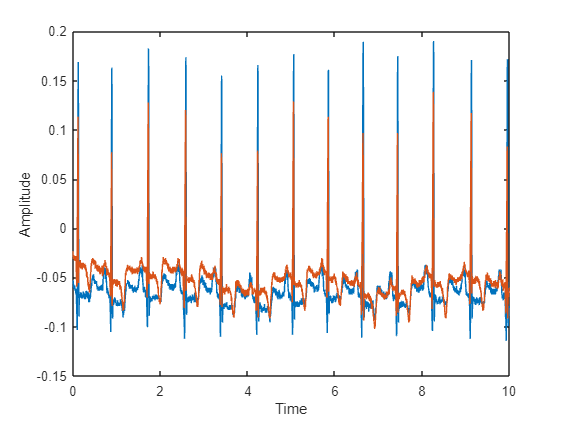

plot(t_og,a_cut)
xlabel("Time")
ylabel("Amplitude")

%encrypted mono channel waveform
t_enc=(0:length(plot_a)-1)/fs

t_enc =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


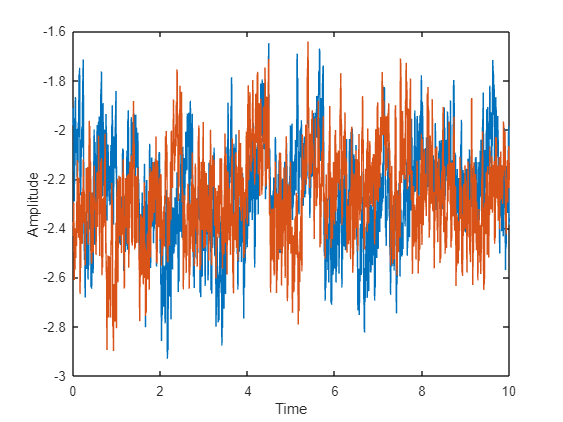


plot(t_enc,plot_a)
xlabel("Time")
ylabel("Amplitude")

writematrix(t_enc,"time_enc.csv")

%original 2 channel waveform

t_og=(0:length(a_cut)-1)/fs

t_og =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


plot(t_og,a_cut,'r')
xlabel("Time")
ylabel("Amplitude")
hold on 
%decrypted 2 channel waveform
t_dec=(0:length(orig)-1)/fs

t_dec =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


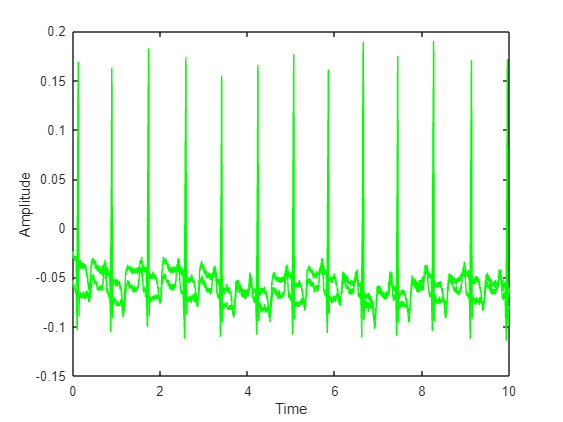

plot(t_dec,orig, 'g')
xlabel("Time")
ylabel("Amplitude")
hold off